# 1 Random Fields

dx = [0.1];
x = [0:dx:1];
y = rand(1, length(x));

## Create a random gaussian field

mu = 0.5;
sigma = 0.25;
y = normrnd(mu, sigma, [1,length(x)]);

### Plot the field

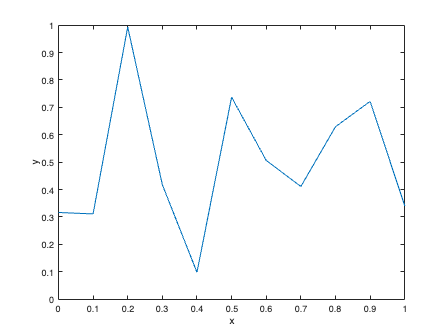

plot(x,y);
xlabel('x');
ylabel('y');

# 2 Correlation

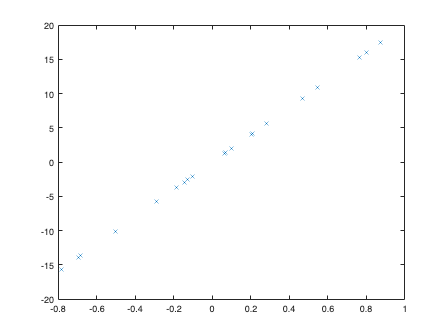

x = -1 + 2*rand(1,20);
y = 20.*x;

plot(x,y,'x');


C = cov(x,y);
cc = C(1,2)

cc = 4.8873


R = corrcoef(x,y);
rho = R(1,2)

rho = 1

# 3 Correlation Structure

## 3.1 Exponential Correlation

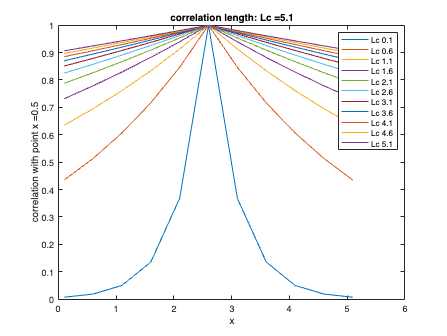


xR = (2.5/5)^1; Lc = 0.2;
x = [0:dx:1];
L = [0.1:dx*5:5.1];

for i=1:length(L)
    Lc = L(i);

% Exponential auto-correlation:
    c = exp(-abs(x-xR)/Lc);
% Plot:
    plot(L,c);
    hold on;
    legend_entries{i} = sprintf('Lc %0.1f', L(i));
end
hold off;
xlabel('x');
ylabel(strcat('correlation with point x = ',num2str(xR))); ylim([0 1]);
title(strcat('correlation length: Lc = ',num2str(Lc)));
legend(legend_entries)

## 3.2 Exponential Squared Correlation

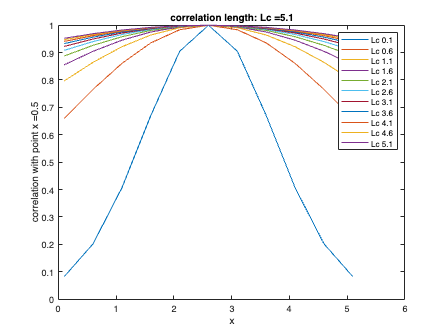

xR = 2.5/5; Lc = 0.2;
x = [0:dx:1];
L = [0.1:dx*5:5.1];
% Exponential auto-correlation:

%c = exp(-abs(x-xR)/Lc);

for i=1:length(L)
    Lc = L(i);

% Squared Exponential auto-correlation:
    c = exp(-abs(x-xR).^2/Lc);
% Plot:
    plot(L,c);
    hold on;
    legend_entries{i} = sprintf('Lc %0.1f', L(i));
end
hold off;
xlabel('x');
ylabel(strcat('correlation with point x = ',num2str(xR))); ylim([0 1]);
title(strcat('correlation length: Lc = ',num2str(Lc)));
legend(legend_entries)

The following points are noted

    **Influence of L**    

- If L is small, the correlation decays quickly, and the points are considered to be uncorrelated if they are far apart.

- If L is large, the correlation decays slowly, and the points are considered to be correlated even if they are far apart.

  **Influence of Structure**

- With 'Squared Exponential Correlation', we can see a  wider range of decay of the correlation and the function is infinitely differentiable, positive definite covariance matrix

- With 'Exponential Correlation', we can see a narrow range of decay, and a sharp peak, meaning that the function is not infinitely differentiable, and not positive definite

# 4 Various Realization

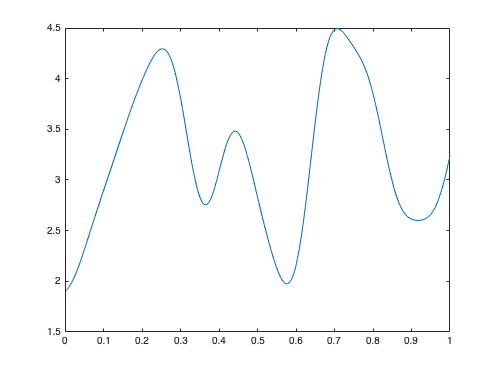

x = [0:0.002:1]; Lc=0.01;
for i=1:length(x) 
    for j=1:length(x)
        D(i,j) = abs(x(i)-x(j));
        C(i,j) = exp(-D(i,j).^2/Lc); 
    end
end
[a,b,c] = svd(C);
mu = 3; 
field = mu;
for i=1:20
    sum = normrnd(0,1)*sqrt(b(i,i))*a(:,i); field = field+sum;
end 
plot(x,field);